# HMM Trajectory Modeling with Multi-Dimensional Data

This example contains MATLAB code for testing **Hidden Markov Models (HMMs)** using **multi-dimensional trajectory data**.

The dataset consists of **synthetically generated 2D and 3D square trajectories**, to which controlled noise is added.

The workflow includes trajectory normalization, dimensionality  reduction, symbolic encoding via a codebook, HMM training, and  trajectory decoding.

The main goal of this project is to explore **symbolic modeling of continuous trajectories** and **temporal pattern learning** using HMMs.

## Initialization and Data Loading

This section initializes the MATLAB environment and loads the synthetic dataset containing a digitally generated square trajectory.

The dataset represents a two-dimensional planar motion and is used as a controlled benchmark for validating the complete HMM–based trajectory modeling pipeline.

The use of synthetic data ensures full control over the underlying geometry and noise characteristics before applying the method to real-world trajectories.

clear all; close all; clc;

%% Select and load trajectory dataset
% Each dataset contains:
%   - pos : NxD position matrix
%   - vel : NxD velocity matrix
%   - t   : Nx1 time vector

trajectory = "square2D.mat";

load(fullfile(trajectory));

N = size(pos,1);          % Number of samples
D = size(pos,2);          % Trajectory dimension (2D or 3D)

fprintf('Loaded trajectory\n Samples: %d | Dimension: %dD\n', N, D);

Loaded trajectory
 Samples: 80 | Dimension: 2D


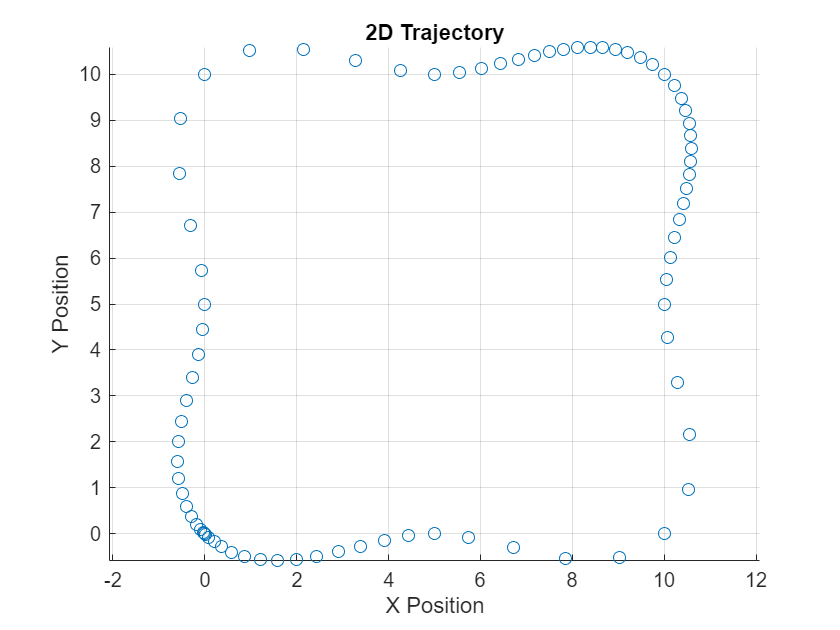

%% Trajectory visualization
figure
if D == 2
    scatter(pos(:,1), pos(:,2))
    axis equal
    xlabel('X Position')
    ylabel('Y Position')
    title('2D Trajectory')
    
elseif D == 3
    scatter3(pos(:,1), pos(:,2), pos(:,3))
    axis tight
    xlabel('X Position')
    ylabel('Y Position')
    zlabel('Z Position')
    title('3D Trajectory')
    
else
    error('Unsupported trajectory dimension.');
end
grid on

## Synthetic Noise Augmentation

To improve robustness and generalization, multiple noisy realizations of the same reference trajectory are generated.

Each realization is treated as an independent training sample while preserving the underlying kinematic structure.

This procedure emulates measurement noise typically observed in real-world sensing systems, such as motion capture or robotic encoders.

% Number of noisy realizations
numRealizations = 100;

% Noise scaling factors (percentage of signal range)
posNoiseRatio = 0.025;   % positional noise [% of range]
velNoiseRatio = 0.01;   % velocity noise [% of range]

% Compute noise amplitudes per dimension
posRange = max(pos) - min(pos);   % 1xD
velRange = max(vel) - min(vel);   % 1xD

np = posNoiseRatio * posRange;
nv = velNoiseRatio * velRange;

% Preallocate container: {pos, vel}
data = cell(numRealizations, 2);

Noise amplitudes are defined as fixed percentages of the dynamic range of the position and velocity signals.

This strategy ensures that the injected perturbations are proportional to the signal magnitude and invariant to absolute scale, allowing the same parameters to be used across trajectories with different units or spatial extents.

- `np` represents the noise amplitude for positional components and is originallyt set to 5% of the position range.

- `nv` represents the noise amplitude for velocity components and is originally set to 1% of the velocity range.

% Generate noisy trajectories
for i = 1:numRealizations
    data{i,1} = pos + np .* (2 * rand(size(pos)) - 1);  % Noisy position trajectory (NxD)
    data{i,2} = vel + nv .* (2 * rand(size(vel)) - 1);  % Noisy velocity trajectory (NxD)
end

For each realization, uniformly distributed random noise is added to both position and velocity signals. The perturbations are generated independently across each time step and spatial dimension to simulate stochastic sensor fluctuations.

The resulting realizations are organized within the `data` cell array, where each row represents an independent training sample:

- `data{i,1}`: Noisy positional trajectory *(N x D).*

- `data{i,2}`: Noisy velocity trajectory *(N x D).*

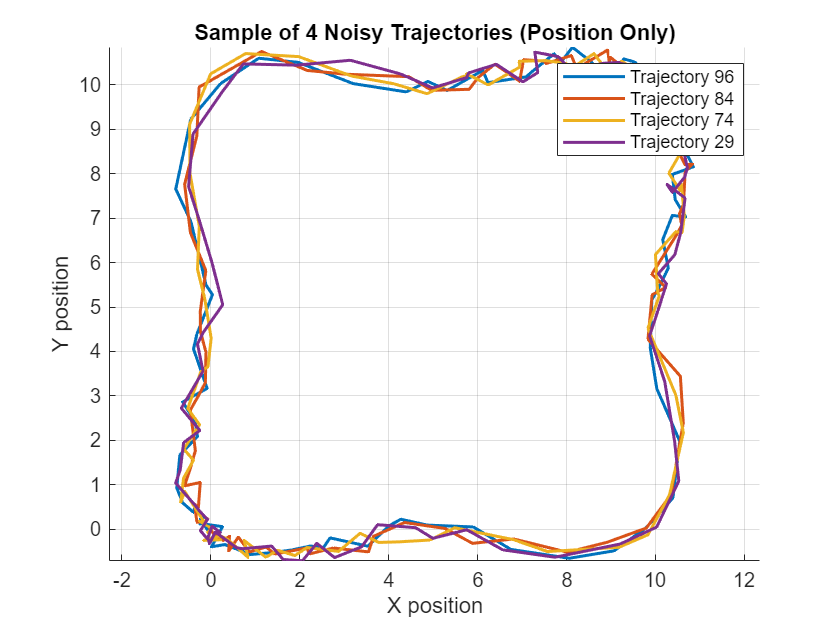

% Select 4 random trajectories
traj_indices = randperm(numRealizations,4);

figure
hold on
colors = lines(4);  % MATLAB's default 4-color palette
if D == 2
    for k = 1:4
        idx = traj_indices(k);
        plot(data{idx,1}(:,1), data{idx,1}(:,2), 'Color', colors(k,:), 'LineWidth', 1.5);
    end
    axis equal
    xlabel('X position')
    ylabel('Y position')

elseif D == 3
    for k = 1:4
        idx = traj_indices(k);
        plot3(data{idx,1}(:,1), data{idx,1}(:,2), data{idx,1}(:,3), 'Color', colors(k,:), 'LineWidth', 1.5);
    end
    view(3)
    xlabel('X Position')
    ylabel('Y Position')
    zlabel('Z Position')
    
else
    error('Unsupported trajectory dimension.');
end

title('Sample of 4 Noisy Trajectories (Position Only)')
legend(arrayfun(@(i) sprintf('Trajectory %d', i), traj_indices, 'UniformOutput', false))
grid on
hold off

## Group-wise Normalization and Trajectory Simplification

Each trajectory is normalized using a group-wise normalization strategy to ensure consistent scaling across heterogeneous dimensions.

Subsequently, the Douglas–Peucker algorithm is applied in an N-dimensional space to reduce trajectory complexity while preserving its geometric structure.

The procedure is independent of the trajectory dimensionality and automatically adapts to planar (2D) or spatial (3D) motion.

### Parameter Definition

First, the key parameters governing trajectory simplification and symbolic discretization are defined.

The Douglas–Peucker tolerance controls the level of geometric detail retained, while the codebook subdivision parameters define the resolution of the symbolic representation.

- `tolerance`: Douglas–Peucker simplification threshold.

- `CB_groups`: Number of subdivisions per dimension for the codebook.

- `w`: Group-wise normalization weights.

%% Parameter Definition

% Douglas–Peucker tolerance
tolerance = 0.01;

% Codebook subdivisions per dimension
CB_pos = 30;    % Position resolution
CB_vel = 5;     % Velocity resolution

CB_groups = [CB_pos*ones(1,D), CB_vel*ones(1,D)];

% NOTE:
% Weights are defined per feature group (pos, vel),
% not per spatial dimension. This ensures scalability
% to both 2D and 3D trajectories.
% [positions | velocities]
w = [1.0 ; 0.5];

### Implementation

For each trajectory:

- **Normalization** is performed using a group-wise weighting scheme, which balances the contribution of different trajectory components (e.g., positions, velocities) and ensures that each dimension is comparably scaled.

- **Geometric simplification** is applied using the N-dimensional Douglas–Peucker algorithm, which retains only the essential points necessary to preserve the shape of the trajectory.

- **Temporal indices** corresponding to the retained points are recovered to maintain the mapping between the simplified trajectory and the original time sequence.

Additionally, the maximum and minimum values of each dimension are recorded across all trajectories. These statistics are later used for reconstructing trajectories and for post-processing of the symbolic sequences.

%% Initialization of containers
numTraj   = size(data,1);
numGroups = size(data,2);   

maxi     = cell(1, numGroups);
mini     = cell(1, numGroups);

RDP      = cell(numTraj, 1);
RDP_time = cell(numTraj, 1);
posnorm  = cell(numTraj, 1);


%% Group-wise normalization and trajectory simplification

for i = 1:numTraj

    % --- Collect trajectory components and statistics ---
    for j = 1:numGroups
        dnorm{j}      = data{i,j};
        maxi{j}(i,:)  = max(data{i,j});
        mini{j}(i,:)  = min(data{i,j});
    end

    % --- Group-wise normalization ---
    posnorm{i} = normGroup(dnorm, w);

    % --- N-D Douglas–Peucker simplification ---
    RDP{i} = douglasPeuckerND_v2(posnorm{i,:}, tolerance);

    % --- Recover temporal indices ---
    for j = 1:size(RDP{i},1)
        RDP_time{i}(j,1) = find( ...
            ismember(posnorm{i}, RDP{i}(j,:), 'rows'), ...
            1);
    end

    % --- Append time for later reconstruction ---
    posnorm{i} = [posnorm{i}, t];

end

- `normGroup.m` performs group-wise normalization of each trajectory, scaling all feature dimensions according to specified weights. This ensures that heterogeneous features, such as positions and velocities, contribute proportionally to subsequent processing steps, including trajectory simplification and symbolic coding.

- `douglasPeuckerND_v2.m` implements a Douglas–Peucker based Simplification algorithm in N-dimensional space. It reduces the number of points in a trajectory while preserving its overall geometric shape, retaining only the most representative points. This simplification decreases computational complexity without significantly altering the trajectory’s essential characteristics.

For further details on the Douglas–Peucker algorithm in N-dimensional applications, see:

Manrique-Cordoba, J., de la Casa-Lillo,  M. Á., & Sabater-Navarro, J. M. (2025). **N-Dimensional Reduction Algorithm for Learning from  Demonstration Path Planning.** *Sensors*, *25*(7), 2145. [https://doi.org/10.3390/s25072145](https://doi.org/10.3390/s25072145) 

## Global Min–Max Statistics and Visualization of Simplified Trajectories

This section computes global minimum and maximum values across all training trajectories.

These statistics are later used to reconstruct continuous trajectories from symbolic representations.

maxmin = cell(1, size(data,2));

for j = 1:size(data,2)
    maxmin{j} = [ ...
        max(maxi{j}, [], 1);   % Global maximum per dimension
        min(mini{j}, [], 1)    % Global minimum per dimension
    ];
end


A subset of trajectories is visualized to qualitatively assess the effects of normalization and simplification.

The original normalized trajectory is shown together with the retained Douglas–Peucker key points.

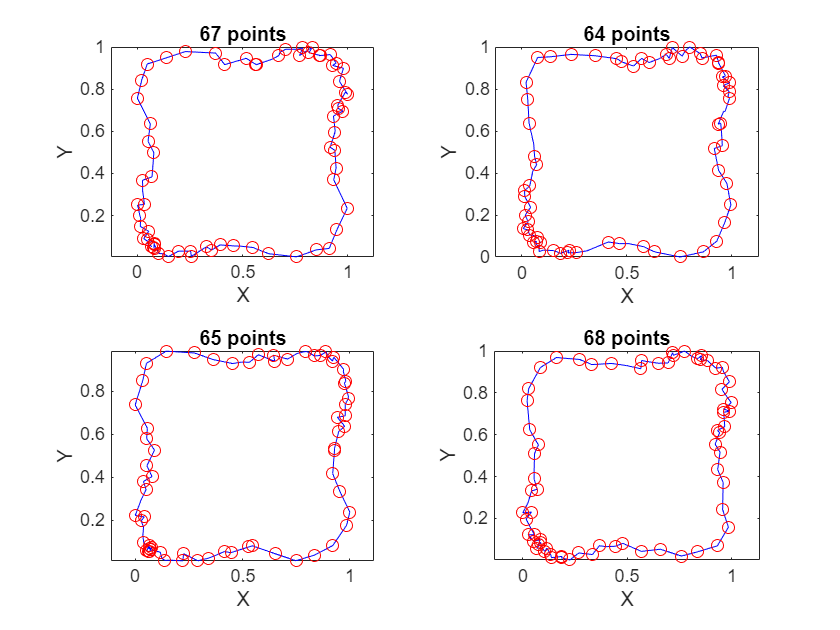

% Select 4 random trajectories
traj_indices = randperm(numRealizations,4);

figure
tiledlayout(2,2)

for i = 1:4

    idx = traj_indices(i);

    norm_pos = posnorm{idx}(:,1:D);    % Normalized position
    RDP_pos  = RDP{idx}(:,1:D);         % Simplified key points

    nexttile
    if D == 2
        plot(norm_pos(:,1), norm_pos(:,2), 'b-', ...
             RDP_pos(:,1),  RDP_pos(:,2),  'ro')
        axis equal
        xlabel('X')
        ylabel('Y')

    elseif D == 3
        plot3(norm_pos(:,1), norm_pos(:,2), norm_pos(:,3), 'b-'); hold on
        plot3(RDP_pos(:,1),  RDP_pos(:,2),  RDP_pos(:,3),  'ro')
        grid on
        xlabel('X')
        ylabel('Y')
        zlabel('Z')
    end

    title([num2str(size(RDP_pos,1)), ' points'])
    hold off
end

% NOTE:
% For visualization purposes, only the positional components
% of the normalized trajectories are shown. Velocity and time
% dimensions are excluded to preserve geometric interpretability.

## Codebook Construction and Symbolic Encoding

The reduced trajectories obtained after Douglas–Peucker simplification are transformed into symbolic representations suitable for HMM training.

Continuous trajectories are mapped to discrete symbols using a finite codebook, enabling the use of discrete observation models.

Only symbols observed in the training data are retained, yielding a compact, data-driven codebook.

### Codebook parameter consistency and expansion

This step ensures consistency between the codebook subdivision parameters and the dimensionality of the feature space.

Group-wise subdivision parameters are expanded to match the full feature dimensionality, allowing the discretization process to adapt automatically to planar or spatial trajectories.

%% Codebook parameter consistency

numGroups = size(data,2);        % e.g., pos, vel
numDims   = size(RDP{1},2);      % total feature dimensions (2D or 3D)

% Expand CB_groups from group-wise to dimension-wise definition
if numel(CB_groups) == numGroups

    CB_expanded = [];
    for i = 1:numGroups
        dim_i = size(data{1,i},2);     % dimensions per group
        CB_expanded = [CB_expanded, ...
                       CB_groups(i) * ones(1, dim_i)];
    end
    CB_groups = CB_expanded;

elseif numel(CB_groups) ~= numDims
    error('ERROR: Incorrect definition of CB_groups.');
end

### Quantization of simplified trajectories

Each dimension of the simplified trajectories is discretized by uniformly subdividing its normalized range according to the corresponding codebook parameter.

This process maps continuous-valued feature vectors into multi-dimensional discrete symbols while preserving the relative geometric structure of the trajectory.

numTraj   = size(RDP,1);
codedTray = cell(numTraj,1);

allSymbols = [];    % For codebook construction

for i = 1:numTraj

    RDP_aux = RDP{i};                 % NxM
    coded_aux = zeros(size(RDP_aux));

    % Dimension-wise quantization
    for m = 1:numel(CB_groups)
        coded_aux(:,m) = floor( ...
            round(RDP_aux(:,m), 2) * CB_groups(m) );
    end

    codedTray{i} = coded_aux;
    allSymbols   = [allSymbols; coded_aux];
end

### Data-driven codebook construction

A compact codebook is constructed by retaining only the discrete symbols that are actually observed in the training trajectories.

This data-driven approach avoids unreachable symbols and reduces the size of the symbolic alphabet used for HMM training.

codebook = unique(allSymbols, 'rows');

### Symbolic encoding for HMM training

Each simplified trajectory is encoded as a sequence of discrete symbols by mapping its quantized feature vectors to indices in the codebook.

The resulting symbol sequences constitute the observation sequences used for training the Hidden Markov Model.

HMMcode = cell(numTraj,1);

for i = 1:numTraj

    coded = codedTray{i};
    codei = zeros(1,size(coded,1));

    for j = 1:size(coded,1)
        HMMcode{i}(1,j) = find(ismember(codebook, coded(j,:), 'rows'), 1);
    end

end

The symbolic alphabet is constructed exclusively from symbols observed in the training data.

This prevents the HMM from allocating probability mass to unreachable states and significantly reduces model complexity.

## HMM Training Preparation and Parameter Configuration

Symbolic trajectory codes are modeled as hidden states, while discretized normalized time is used as the observable variable.

This formulation enables the HMM to learn a probabilistic relationship between temporal progression and spatial motion patterns, providing robustness to temporal variability and supporting trajectory resynthesis under novel timing conditions.

% Weight for temporal normalization (single observable group)
wt = 1.0;

% Number of temporal observation groups
% Defined as 80% of the shortest simplified trajectory
minSeqLength = min(cellfun(@(x) size(x,1), RDP));
Gt = round(0.8 * minSeqLength);

% Preallocate temporal observation sequences
normT = cell(numRealizations,1);
T_gn  = cell(numRealizations,1);

for i = 1:numRealizations

    % Normalize temporal indices of retained trajectory points
    normT{i} = normGroup(RDP_time(i), wt)';

    % Discretize normalized time into observable symbols
    T_gn{i} = floor(round(normT{i},2) * Gt) + 1;
end

### HMM sequences

Hidden state sequences are formed by concatenating symbolic trajectory codes from all training demonstrations, while observable sequences are built from the corresponding discretized temporal progressions.

% Hidden state sequences (symbolic trajectory codes)
hidd_states = horzcat(HMMcode{:});

% Observable sequences (discretized temporal progression)
seq_obs = horzcat(T_gn{:});


## HMM Pseudotransition Estimation and Initialization and Training

This section initializes and trains the Hidden Markov Model using symbolic trajectory states as hidden variables and discretized time as observations.

The number of hidden states and observable symbols is inferred directly from the encoded sequences, resulting in a fully data-driven model structure.

Transition probabilities are initialized uniformly and estimated using pseudotransitions to improve numerical stability and prevent zero-probability transitions during training.

% Number of hidden states (symbolic trajectory codes)
nStates = max(hidd_states);

% Uniform initialization of the transition matrix
A0 = ones(nStates, nStates) / nStates;

%% HMM Training with Pseudotransitions (Transitions only)

[TRANSps, EMISps] = hmmestimate( ...
    seq_obs, ...
    hidd_states, ...
    'Pseudotransitions', A0);

### HMM Matrices Visualization

This visualization provides a qualitative assessment of the learned model parameters. The **Transition Matrix (TRANSps)** illustrates the probability flow between hidden states, while the **Emission Matrix (EMISps)** shows the relationship between hidden states and observable symbols. Darkness or color intensity indicates higher probability weights.

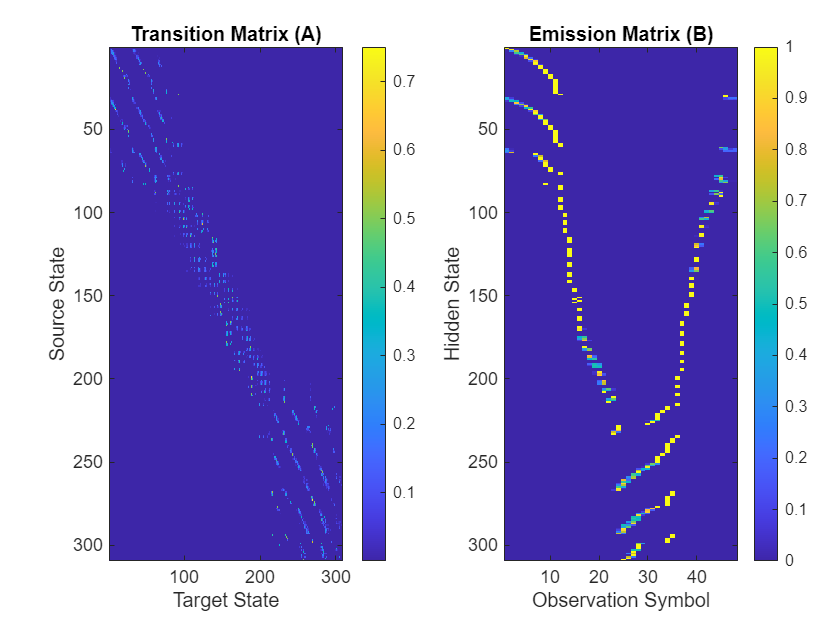

figure;
t = tiledlayout(1, 2, 'TileSpacing', 'Compact');

% Transition Matrix Visualization
nexttile;
imagesc(TRANSps); 
colormap(parula);
colorbar;
title('Transition Matrix (A)');
xlabel('Target State');
ylabel('Source State');

% Emission Matrix Visualization
nexttile;
imagesc(EMISps);
colormap(parula);
colorbar;
title('Emission Matrix (B)');
xlabel('Observation Symbol');
ylabel('Hidden State');

# HMM Evaluation Using a Low-Noise Verification Trajectory

This section evaluates the trained HMM using a synthetic verification trajectory with minimal noise, designed to emulate the best-quality execution from the training dataset.

The procedure mirrors the standard evaluation pipeline: the test trajectory is normalized, simplified, and temporal observations are discretized. The HMM then infers the most probable symbolic state sequence, which can later be reconstructed into continuous trajectory data.

### Verification Trajectory Generation

Generate a low-noise verification trajectory that emulates the best-quality execution from the training dataset.

Noise amplitudes are defined relative to the dynamic range of each trajectory dimension to maintain proportionality and scale invariance.

Noise level can be adjusted from 0 (no noise) to 0.02 (2% of the signal range), with a default value of 0.01 (1%). 

% Noise ratios to simulate "ideal" trajectory
noiseRatioPos = 0.01;   % positional noise [% of range]
noiseRatioVel = 0.01;   % velocity noise [% of range]

% Compute dynamic ranges per dimension
posRange = max(pos) - min(pos);   % 1xD
velRange = max(vel) - min(vel);   % 1xD

% Compute noise amplitudes
np = noiseRatioPos * posRange;
nv = noiseRatioVel * velRange;

% Generate low-noise verification trajectory
test_data{1,1} = pos + np .* (2 * rand(size(pos)) - 1);  
test_data{1,2} = vel + nv .* (2 * rand(size(vel)) - 1); 

### Normalization and Trajectory Simplification

The verification trajectory is normalized using group-wise scaling and simplified with the Douglas–Peucker algorithm.

A quantized version of the trajectory is optionally computed for intermediate checks.

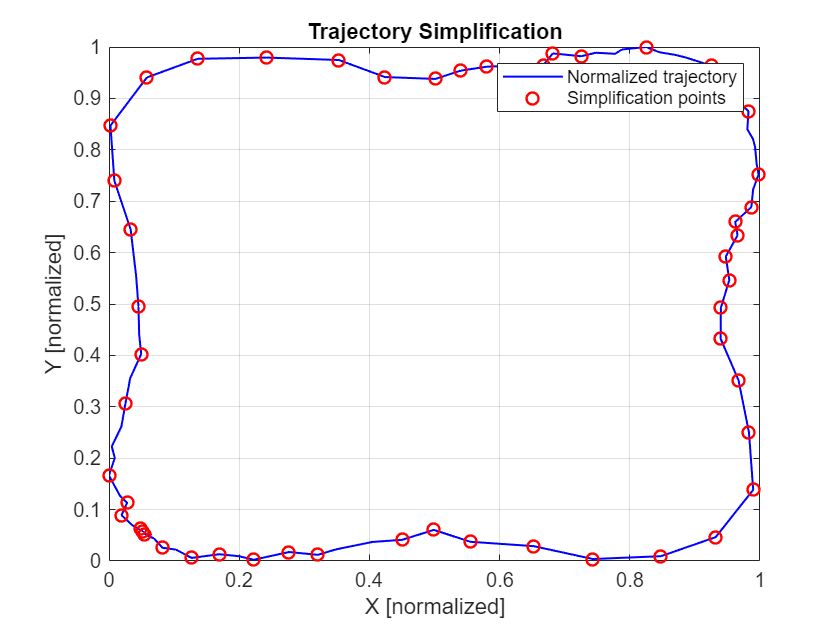

%% Normalization and Douglas–Peucker simplification
posnorm_test = normGroup(test_data, w);                   % group-wise normalization
RDP_test     = douglasPeuckerND_v2(posnorm_test, tolerance);  % trajectory simplification

% Optional quantized version for debugging / visualization
coded_test   = round(RDP_test*2,2)*10;

%% Scatter plot: normalized trajectory with RDP points overlaid
figure

if D == 2
    % 2D plot
    plot(posnorm_test(:,1), posnorm_test(:,2), 'b-', 'LineWidth', 1); 
    hold on
    plot(RDP_test(:,1), RDP_test(:,2), 'ro', 'LineWidth', 1.2);        
    xlabel('X [normalized]');
    ylabel('Y [normalized]');
    legend('Normalized trajectory', 'Simplification points');
    grid on

elseif D == 3
    % 3D plot
    scatter3(posnorm_test(:,1), posnorm_test(:,2), posnorm_test(:,3), 20, 'b-', 'LineWidth', 1);
    hold on
    plot3(RDP_test(:,1), RDP_test(:,2), RDP_test(:,3), 'ro', 'LineWidth', 1.2);
    xlabel('X [normalized]');
    ylabel('Y [normalized]');
    zlabel('Z [normalized]');
    legend('Normalized trajectory', 'Simplification points');
    grid on

end
title('Trajectory Simplification');

### Temporal Index Recovery

Recover the temporal correspondence of each simplified point relative to the normalized trajectory.

This ensures correct alignment between spatial simplification and temporal observations for HMM decoding.

t_testi = knnsearch(posnorm_test, RDP_test);

### Temporal Normalization and Discretization

Convert temporal indices into a normalized and discretized observable sequence for the HMM.

The resulting sequence aligns with the symbolic hidden states.

coded_auxt = normGroup({t_testi}, wt);   % normalize temporal indices with group weights
t_test     = floor(round(coded_auxt,2) * Gt) + 1;  % scale to integer observable indices

## HMM State Inference, Symbolic Decoding, and Trajectory Reconstruction

This section infers the most probable sequence of hidden symbolic states using the **Viterbi algorithm** and reconstructs the corresponding continuous trajectory.

The reconstructed trajectory is then compared qualitatively with the verification trajectory.

### HMM State Inference (Viterbi Decoding)

Given the discretized temporal sequence (`t_test`), the HMM infers the most probable hidden symbolic states using the Viterbi algorithm.

%% HMM Viterbi decoding
STATES = hmmviterbi(t_test,TRANSps,EMISps);

### Symbolic Decoding

Map the HMM-inferred states back to **continuous trajectory points** using the data-driven codebook.

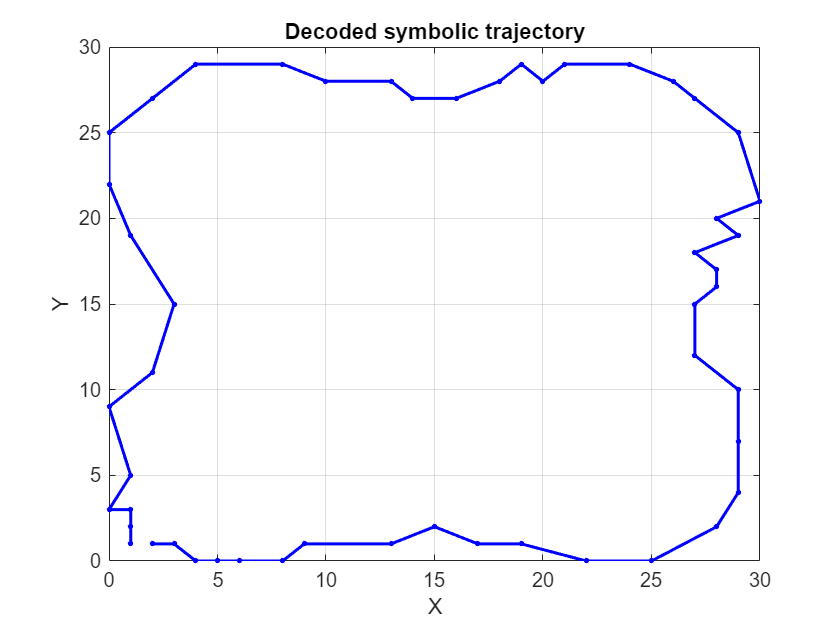

%% Symbolic decoding
decoded = zeros(length(STATES), size(codebook,2));  % preallocate
for i = 1:length(STATES)
    decoded(i,:) = codebook(STATES(i),:);
end

%% Quick plot of decoded symbolic trajectory (2D or 3D)
figure

if D == 2
    plot(decoded(:,1), decoded(:,2), 'b.-', 'LineWidth', 1.5, 'MarkerSize', 8);
    xlabel('X');
    ylabel('Y');

elseif D == 3
    plot3(decoded(:,1), decoded(:,2), decoded(:,3), 'b.-', 'LineWidth', 1.5, 'MarkerSize', 8);
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
end

title('Decoded symbolic trajectory');
grid on

### Post-processing / Continuous Trajectory Reconstruction

Map the decoded symbolic trajectory back to **physical units** using global min–max statistics and codebook group definitions (`normDecode`).

This reconstructs a smooth trajectory comparable with the verification trajectory.

decodednorm = normDecode(decoded, maxmin, CB_groups);  % group-wise normalization   

### Trajectory Visualization

Visual qualitative assessment of reconstruction accuracy in 2D and 3D.

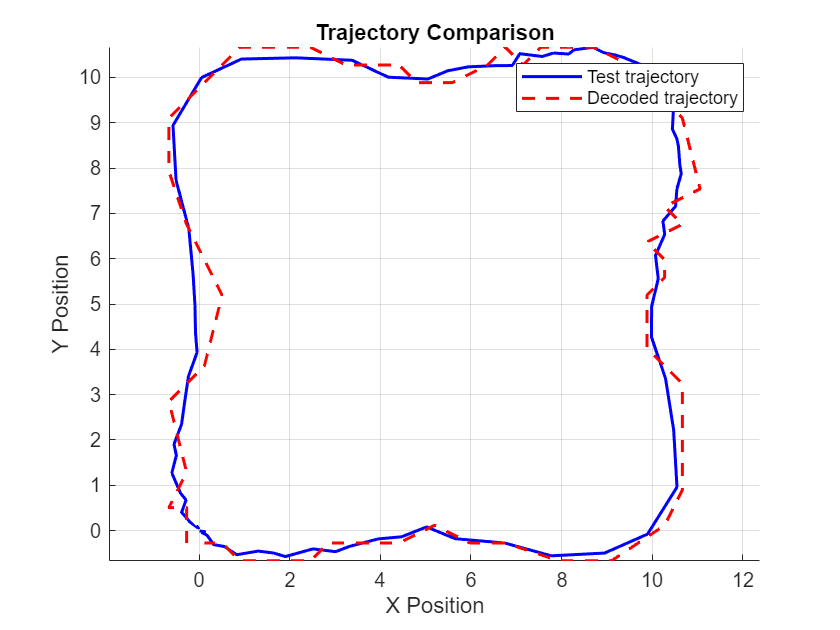

figure
hold on
if D == 2
    plot(test_data{1}(:,1), test_data{1}(:,2), 'b-', 'LineWidth', 1.5);
    plot(decodednorm{1}(:,1), decodednorm{1}(:,2), 'r--', 'LineWidth', 1.5);
    xlabel('X Position')
    ylabel('Y Position')

elseif D == 3
    plot3(test_data{1}(:,1), test_data{1}(:,2), test_data{1}(:,3), 'b-', 'LineWidth', 1.5);
    plot3(decodednorm{1}(:,1), decodednorm{1}(:,2), decodednorm{1}(:,3), 'r--', 'LineWidth', 1.5);
    xlabel('X Position')
    ylabel('Y Position')
    zlabel('Z Position')
    
end
title('Trajectory Comparison')
legend('Test trajectory', 'Decoded trajectory')
grid on
axis equal